# Video Pre-Processing Algorithm Analysis: Background Generation (Part A, Basic Method)

**Summary**: Test background generation method on a series of videos.

- Of the 'basic' methods evaluated, median / mode gave the best results. However, median is faster to compute than mode. 

- Quality of background generated using median method is satisfactory for WAT videos, but seemed to be inconsistent with other types of videos. 

SWC, 14 Feb 2021.

clear all 

## A) 'Basic' statistical method

Shows 3 methods: i) Median, ii) Mean, iii) Mode

- WAT videos

Processed video: WAT001_SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0006.avi
Median; Elapsed time = 1.52
Mode; Elapsed time = 1.87
Mean; Elapsed time = 3.81


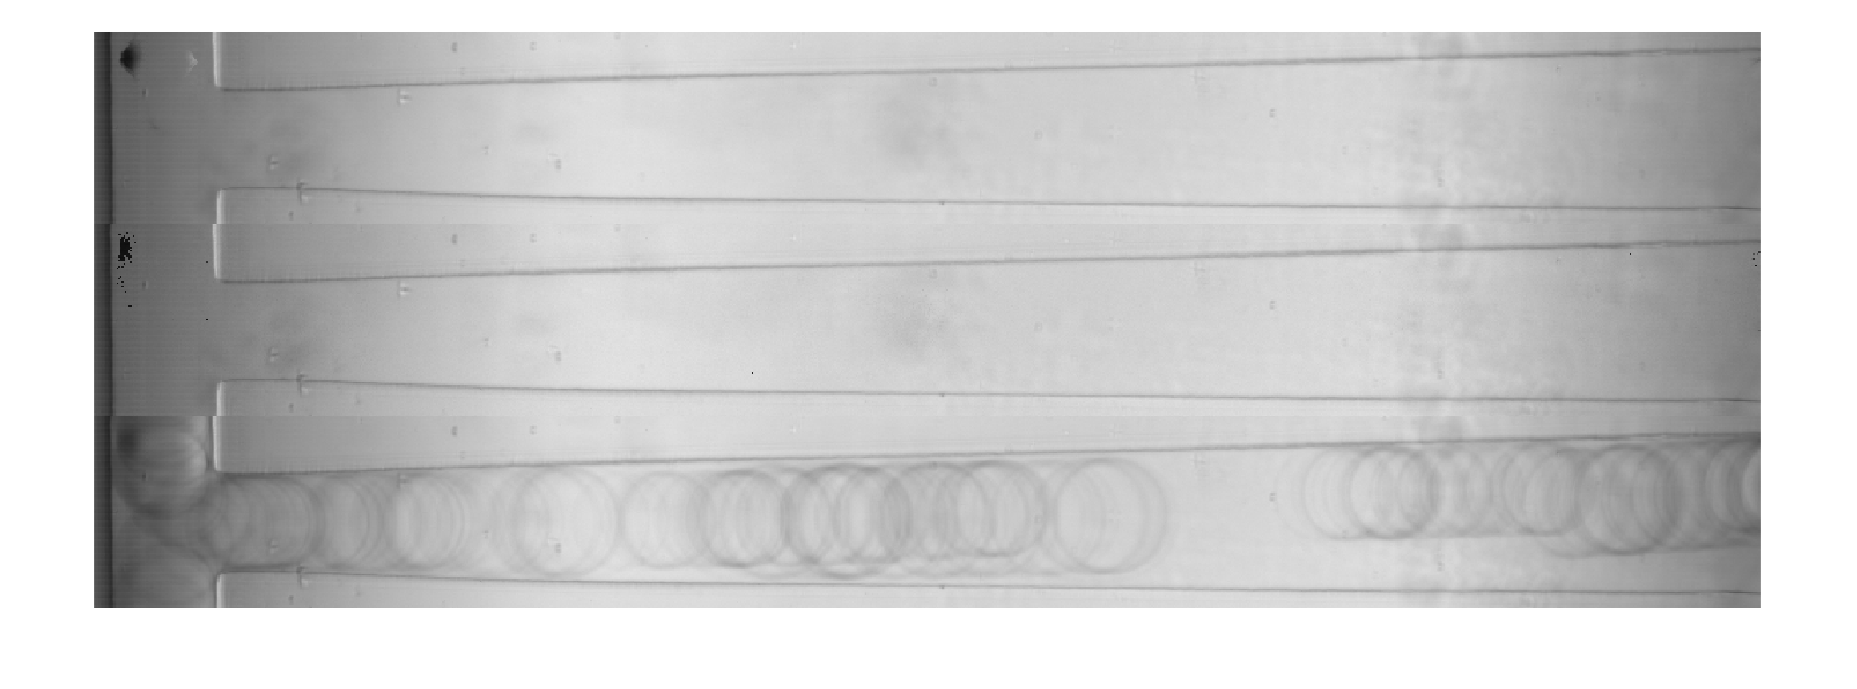

-------------------------------------------


Processed video: WAT002_SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0023.avi
Median; Elapsed time = 1.48
Mode; Elapsed time = 1.79
Mean; Elapsed time = 3.55


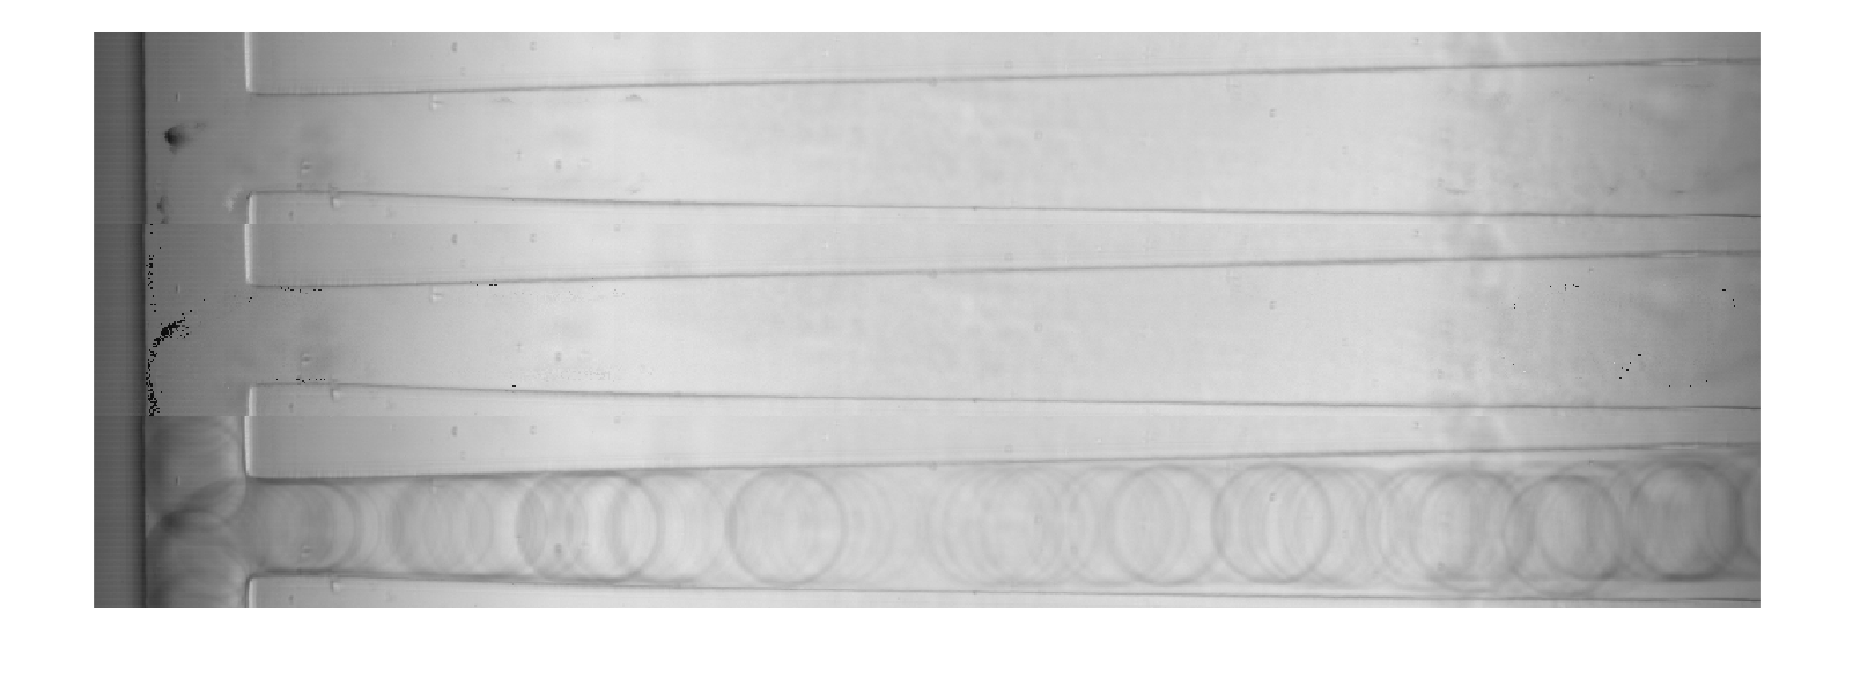

-------------------------------------------


Processed video: WAT003_SO5_13umL-7Wat_umL-10kfps x4mag_sh50_C001H001S0057.avi
Median; Elapsed time = 7.22
Mode; Elapsed time = 9.99
Mean; Elapsed time = 19.22


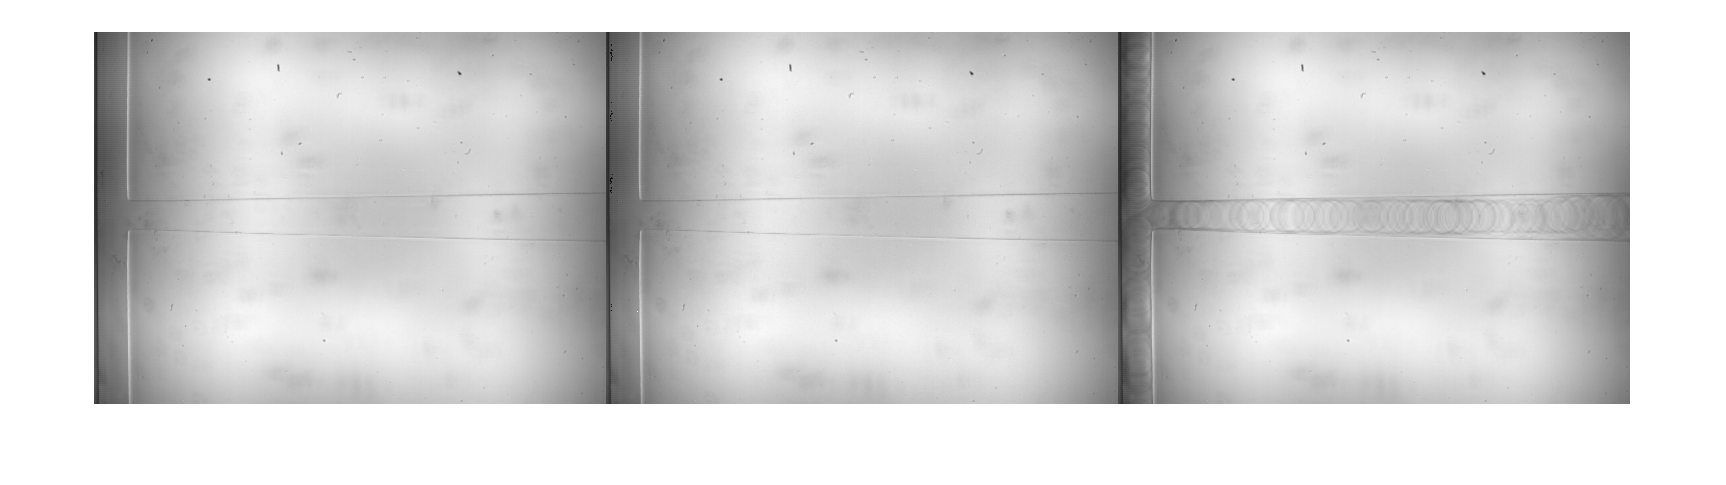

-------------------------------------------


Processed video: WAT004_SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi
Median; Elapsed time = 5.82
Mode; Elapsed time = 7.37
Mean; Elapsed time = 16.69


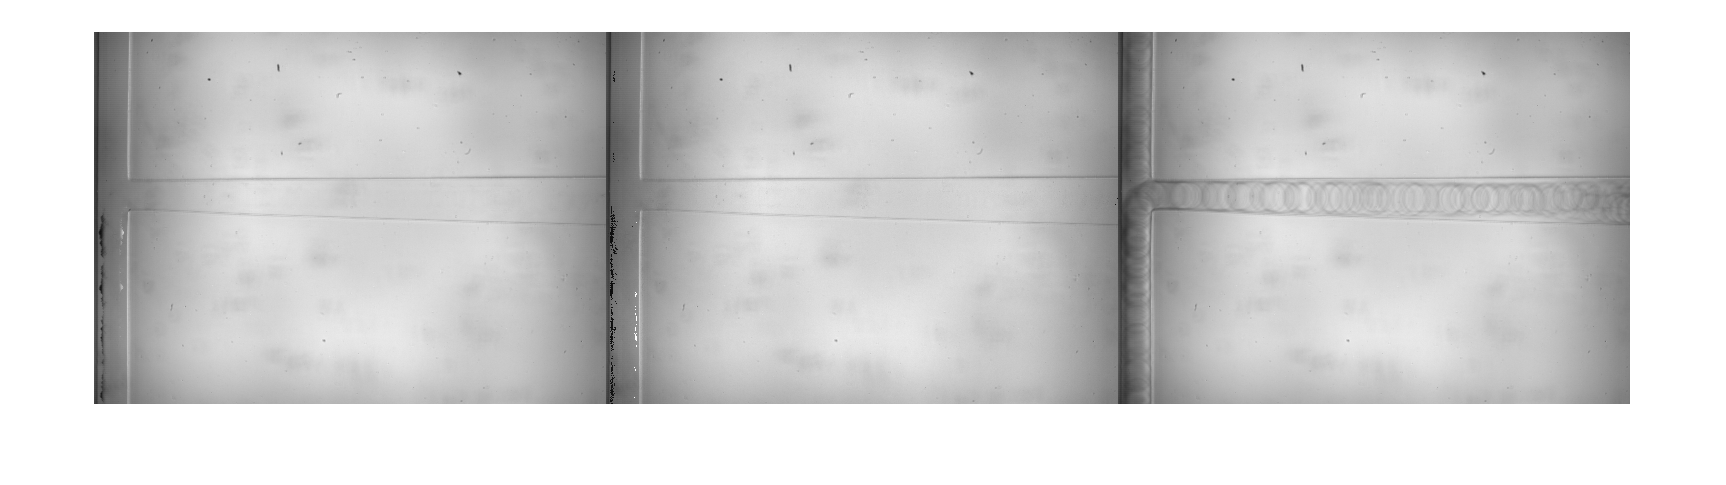

-------------------------------------------


Processed video: WAT005_SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0036.avi
Median; Elapsed time = 5.40
Mode; Elapsed time = 7.10
Mean; Elapsed time = 16.97


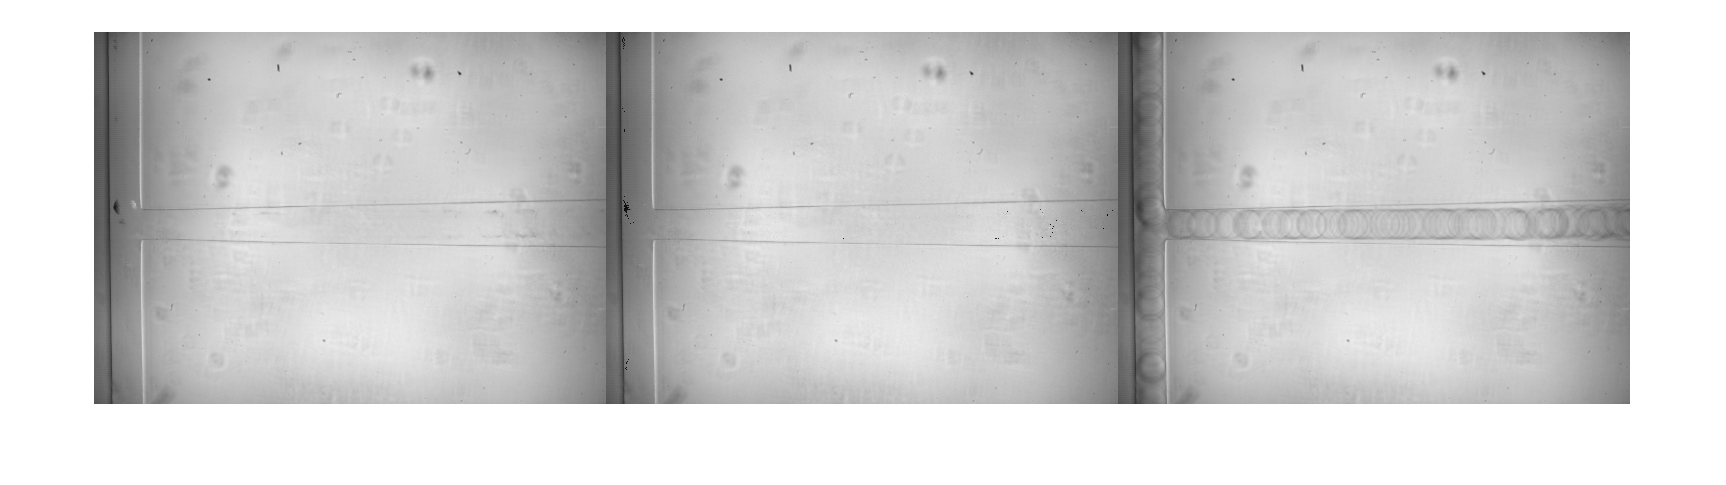

-------------------------------------------


Processed video: WAT006_SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0041.avi
Median; Elapsed time = 1.43
Mode; Elapsed time = 1.67
Mean; Elapsed time = 3.12


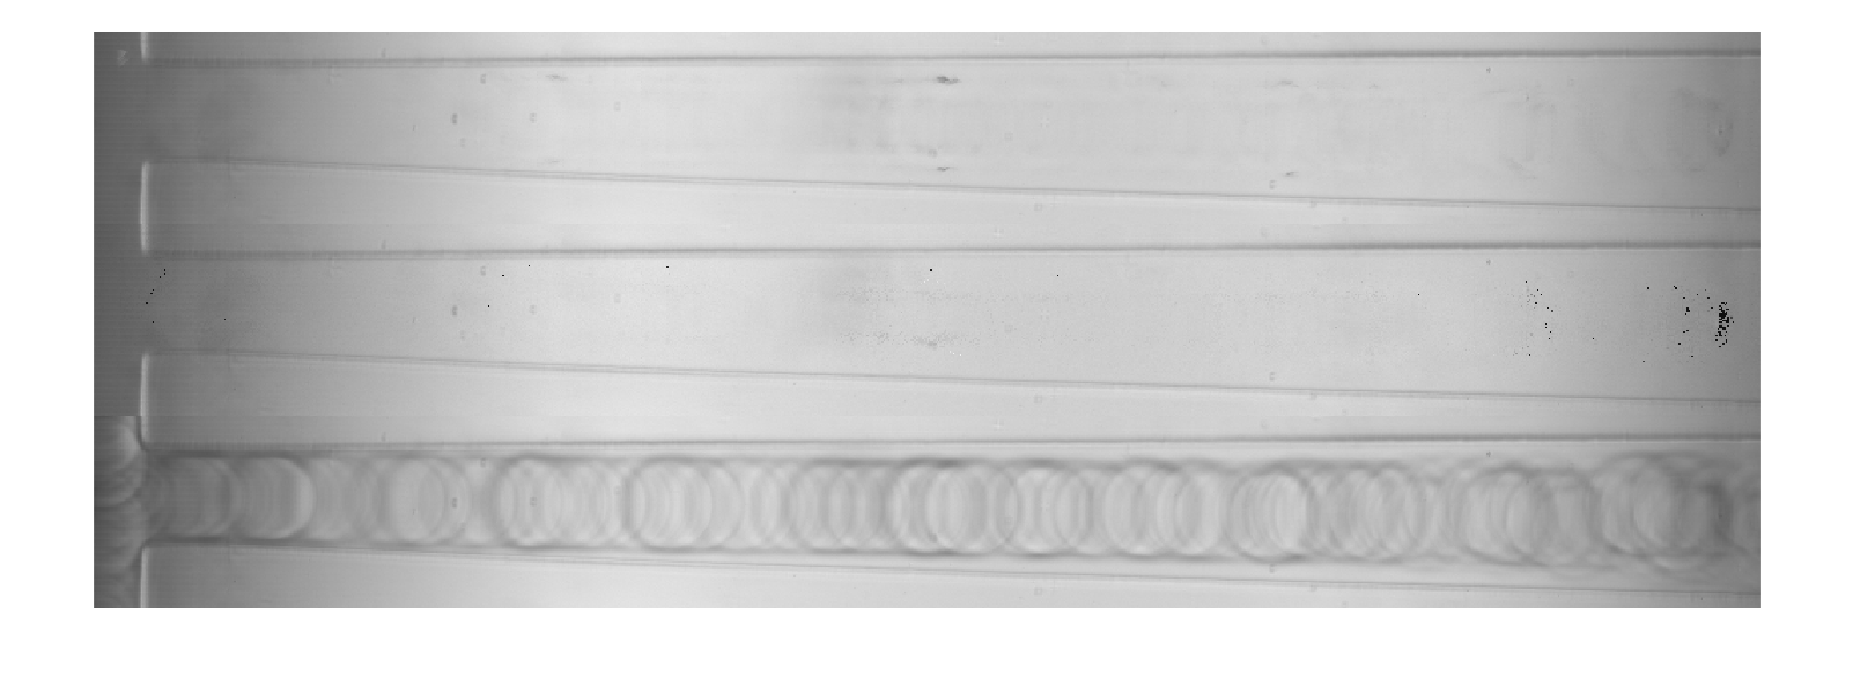

-------------------------------------------


vid_files = dir('WAT*.avi');

for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name 
    n = 50; 
    
    [med_bg mod_bg avg] = bgGenBasic(vid_name, n);
    
    disp('-------------------------------------------')

    
end

- Triton videos

vid_files = dir('TRI*.avi');

for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name 
    n = 50; 
    
    [med_bg mod_bg avg] = bgGenBasic(vid_name, n);
    
    disp('-------------------------------------------')
    
end

- SDS videos

vid_files = dir('SDS*.avi');

for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name 
    n = 50; 
    
    [med_bg mod_bg avg] = bgGenBasic(vid_name, n);
    
    disp('-------------------------------------------')
    
end

- C12TAB videos

vid_files = dir('C12T*.avi');

for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name 
    n = 50; 
    
    [med_bg mod_bg avg] = bgGenBasic(vid_name, n);
    
    disp('-------------------------------------------')
    
end

- DYE videos

% clear all 

vid_files = dir('DYE*.avi');

for i = 1:numel(vid_files)
    vid_name = vid_files(i).name; % get video file name 
    n = 50; 
    
    [med_bg mod_bg avg] = bgGenBasic(vid_name, n);
    
    disp('-------------------------------------------')
    
end